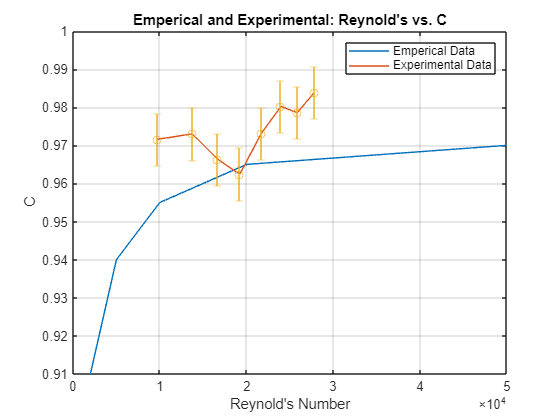

% AE 341 Lab 2
clc, clear
    
% ------------------------------------------------------------------------
% Data
% ------------------------------------------------------------------------

V1 = [25; 25; 25; 15; 15; 15; 15; 15]; % L
V2 = [35; 35; 35; 25; 25; 25; 25; 25];
t1 = [42.04; 45.25; 48.93; 32.24; 36.51; 42.07; 51.09; 72.23]; % s
t2 = [58.77; 63.07; 67.82; 53.7; 60.61; 69.57; 84.75; 120.25];

dh1T = (400:-50:50)'/1000; % m
dh12 = [105; 80; 75; 60; 45; 30; 20; 10]/1000;

Temp = 18; % C
D1 = .026; % m
DT = .016;
D2 = D1;
A1 = 5.3e-4; % m^2
AT = 2e-4;
A2 = A1;
p = 998.68; % kg/m^3
dv = 1.05; %Ns/m^2
g = 9.795; % m/s^2

Re_E = [2; 5; 10; 20; 50] .* 1000;
C_E = [.910; .940; .955; .965; .970];

% ------------------------------------------------------------------------
% Calculations
% ------------------------------------------------------------------------

Q1 = V1 ./ t1;
Q2 = V2 ./ t2;
Q_e = (Q1 + Q2) /2;

V1_e = Q_e / A1;
ReD = (V1_e .* D1 .* p) ./ dv; % kg/m*s
Q_t = AT .* sqrt((2.*g.*dh1T)/(1-((DT/D1)^4))) *1000;
C = Q_e ./ Q_t;
err = (.95 .* (std(C) ./ sqrt(C)));

coe = polyfit(dh1T, dh12, 1);
xF = linspace(min(dh1T), max(dh1T), 1000);
yF = polyval(coe, xF);


pHeadLoss = dh12./dh1T;

% ------------------------------------------------------------------------
% Plot
% ------------------------------------------------------------------------

figure(1)
plot(Re_E, C_E)
hold on
plot(ReD,C)
errorbar(ReD,C,err,'o')

grid on
xlabel("Reynold's Number")
ylabel('C')
title("Emperical and Experimental: Reynold's vs. C")
legend('Emperical Data', 'Experimental Data', 'Location', 'NorthEast')
hold off

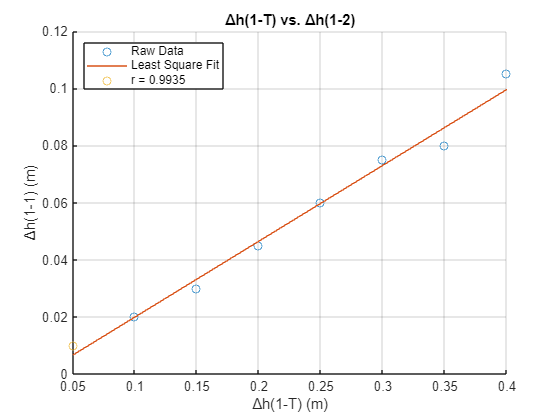


figure(2)
scatter(dh1T, dh12)
hold on
plot(xF, yF)
scatter(min(dh1T),min(dh12))
grid on
xlabel("Δh(1-T) (m)")
ylabel('Δh(1-1) (m)')
title("Δh(1-T) vs. Δh(1-2)")
legend('Raw Data', 'Least Square Fit', 'r = 0.9935', 'Location', 'NorthWest')
hold off